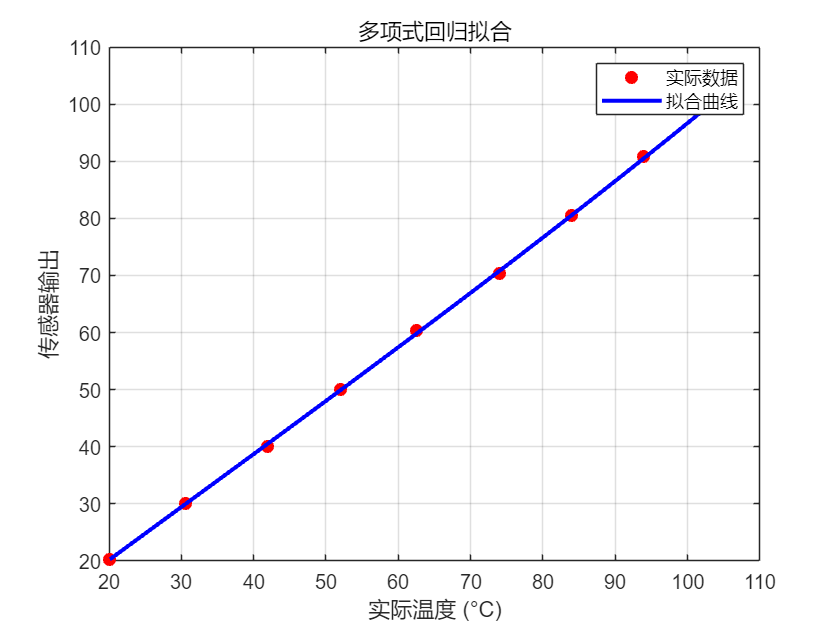

% 假设 x_data 是传感器的实际温度值（例如，采集的温度）
% 假设 y_data 是传感器的输出值（例如，传感器读取的电阻或电压）

% 示例数据（你可以用实际的采集数据替换它们）
x_data = [20.124152, 30.545056, 41.951276, 52.025478, 62.444781, 73.954872, 84.004858, 93.954781, 103.874125];  % 温度数据
y_data = [20.324122, 30.021035, 40.121548, 50.098754, 60.284715, 70.354784, 80.421654, 90.754214, 100.654874];  % 传感器输出数据

% 设置拟合的多项式阶数
poly_degree = 3;  % 例如，3阶多项式

% 执行多项式拟合
[p, S, mu] = polyfit(x_data, y_data, poly_degree);

% p: 多项式的系数（从高阶到低阶）
% S: 拟合的标准误差
% mu: 数据的均值和标准差，用于归一化

% 生成拟合曲线
x_fit = linspace(min(x_data), max(x_data), 100);  % 生成拟合曲线的x值
y_fit = polyval(p, x_fit, S, mu);  % 根据多项式系数计算拟合的y值

% 绘制数据点和拟合曲线
figure;
plot(x_data, y_data, 'ro', 'MarkerFaceColor', 'r');  % 绘制实际数据点
hold on;
plot(x_fit, y_fit, 'b-', 'LineWidth', 2);  % 绘制拟合曲线
xlabel('实际温度 (°C)');
ylabel('传感器输出');
title('多项式回归拟合');
legend('实际数据', '拟合曲线');
grid on;


% 输出拟合的多项式系数
disp('拟合的多项式系数：');

拟合的多项式系数：


disp(p);

    0.1661    0.5613   27.3395   59.8430




% 如果需要，可以评估拟合的误差
% 拟合的标准误差
disp('拟合的标准误差：');

拟合的标准误差：


disp(S);

        R: [4×4 double]
       df: 5
    normr: 0.8609

